clear
numd = [1 -0.1];
dend = conv([1 -0.8], [1 -0.9]);
N_sim = 60;
k = 1: (N_sim);
% impulse resonse data from transfer function
H = dimpulse(numd, dend, k);
% discrete time Laguerre functions 
a = 0.8, N = 3

a = 0.8000

N = 3

[Al, L0] = lagd(a, N);
L(:, 1) = L0;
for kk = 2:N_sim
	L(:, kk) = Al*L(:, kk-1);
end
% the coefficients of the Laguerre model
c1 = L(1, :)*H, N

c1 = 4.3810

N = 3

c2 = L(2, :)*H

c2 = 6.8694

c3 = L(3, :)*H

c3 = 2.3762

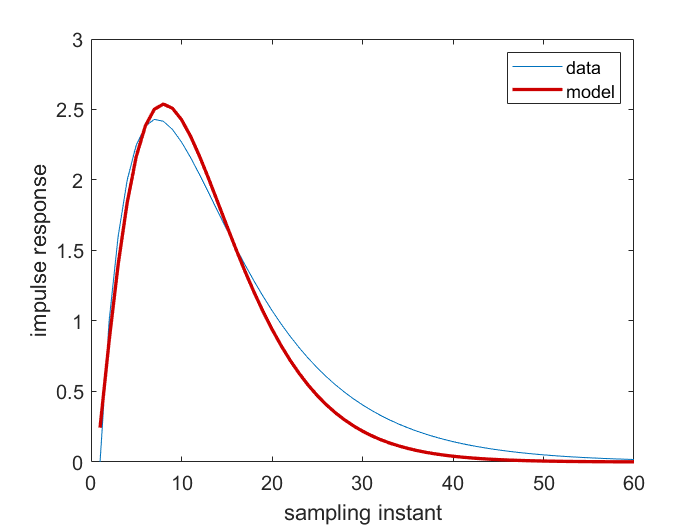

H_model = c1*L(1, :) + c2*L(2, :) + c3*L(3, :);
figure, plot(k, H), hold on
plot(k, H_model, 'linewidth', 2, 'color', [0.8, 0 0])
set(gca, 'FontSize', 12, 'FontName', 'helvetica')
legend 'data' 'model', xlabel 'sampling instant', ylabel 'impulse response'

## orthonormality check

L(:, 1)*L(:, 1)'
L(:, 2)*L(:, 2)'